正在模拟 100 条 SDE 轨迹...


SDE 模拟完成，耗时: 0.1705 秒


filename1 = 'damage_traj 1.pdf'

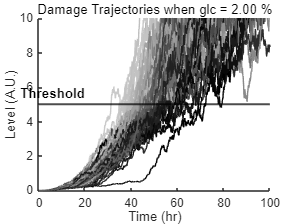

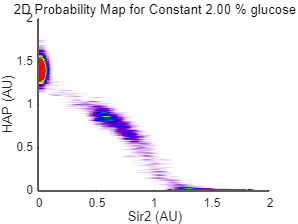

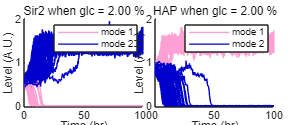


模拟完成。Mode 1 轨迹数量: 25, Mode 2 轨迹数量: 75


正在模拟 100 条 SDE 轨迹...


SDE 模拟完成，耗时: 0.4501 秒


filename1 = 'damage_traj 2.pdf'

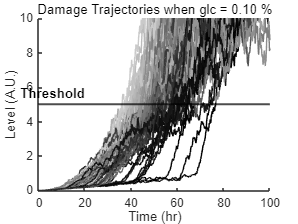

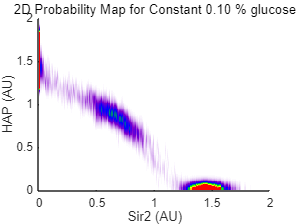

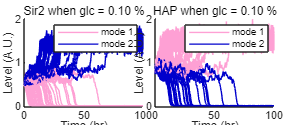


模拟完成。Mode 1 轨迹数量: 66, Mode 2 轨迹数量: 34


正在模拟 100 条 SDE 轨迹...


SDE 模拟完成，耗时: 0.4409 秒


filename1 = 'damage_traj 3.pdf'

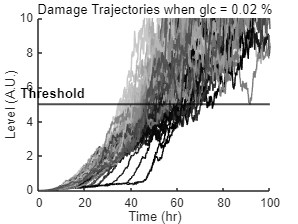

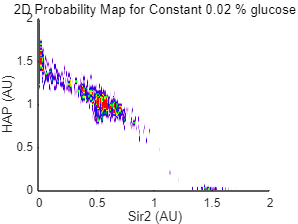

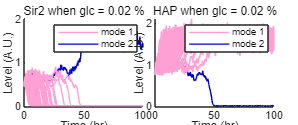


模拟完成。Mode 1 轨迹数量: 99, Mode 2 轨迹数量: 1


% 清理工作区
clear;
clc;
close all;

%% 1. 定义参数
% 从图四的表格中获取参数值
params = struct();
params.beta1 = 0.01;      % h^-1
params.beta2 = 0.01;      % h^-1
params.KS = 0.52;
params.KH = 0.62;
params.dS = 0.1;        % h^-1
params.dH = 0.3;        % h^-1
params.gamma1 = 1;
params.gamma2 = 1;      % 假设 gamma2 = 1 (非 2xSir2)
params.n1 = 3;
params.n2 = 3;
params.aSt = 0.052;
params.aHt = 0.126;
params.KSt = 0.03;
params.KHt = 0.04;
params.kSt = -0.02;
params.kHt = -0.06;
params.bSt = 1.62;
params.bHt = 2.00;
params.epsilonS = 0.28; % 噪声强度 epsilon_S
params.epsilonH = 0.28; % 噪声强度 epsilon_H

%% 2. 定义 S_total(D) 和 H_total(D) 函数 (根据图二)
D_val = [2 0.1 0.02]; % 示例 D 值，请根据您的具体问题设置，这个值可能决定了双稳态的区域
for j=1:3
    S_total_func = @(D, params) params.aSt * (params.KSt^3 / (params.KSt^3 + D^3)) + params.kSt * D + params.bSt;
    H_total_func = @(D, params) params.aHt * (params.KHt^3 / (params.KHt^3 + D^3)) + params.kHt * D + params.bHt;
    S_total_D = S_total_func(D_val(j), params);
    H_total_D = H_total_func(D_val(j), params);

    %% 3. 定义带有随机项的常微分方程 (SDEs)
    sdes_func = @(t, x, params, S_total_D, H_total_D) [
        (params.beta1 + x(1)^params.n1 / (params.KS^params.n1 + x(1)^params.n1)) * (S_total_D - x(1)) - (params.dS + params.gamma1 * x(2)) * x(1);
        (params.beta2 + x(2)^params.n2 / (params.KH^params.n2 + x(2)^params.n2)) * (H_total_D - x(2)) - (params.dH + params.gamma2 * x(1)) * x(2)
];
    diffusion_coeffs = [params.epsilonS; params.epsilonH];

    %% 4. 模拟多条 SDE 轨迹并分类
    % 设置模拟参数
    dt = 0.1;      % 时间步长
    T = 100;        % 模拟总时长 (根据图 E，100小时足够)
    num_steps = T / dt;
    t_span = 0:dt:T;

    num_trajectories = 100; % 模拟的轨迹数量，可以调整以获得更多数据
    S0 = 0.5; H0 = 0.8; % 初始条件，可以设置为一个在两个吸引子之间的地方
    initial_conditions = repmat([S0; H0], 1, num_trajectories); % 所有轨迹从相同初始条件开始

    % 存储所有轨迹，为了方便分类和绘图
    % Cell 数组可以存储不同长度的轨迹，但这里轨迹长度相同，所以直接用三维数组
    all_S_trajectories = zeros(num_steps + 1, num_trajectories);  
    all_H_trajectories = zeros(num_steps + 1, num_trajectories);
    all_F_trajectories = zeros(num_steps + 1, num_trajectories);
    hit_time = zeros(1, num_trajectories);

    % Mode 1 对应 HAP (S) 高，Sir2 (H) 低
    % Mode 2 对应 HAP (S) 低，Sir2 (H) 高
    % 这些阈值是关键，请根据您系统真实的双稳态值调整
    threshold_S = 0.05; % 例如，S值低于此阈值为Mode 2，高于此阈值为Mode 1
    threshold_H = 0.1; 

    fprintf('正在模拟 %d 条 SDE 轨迹...\n', num_trajectories);
    tic; % 计时开始

    for traj_idx = 1:num_trajectories
        X = initial_conditions(:, traj_idx); % 获取当前轨迹的初始条件
        Y = 0;
    
        %存储当前轨迹的数据
        current_S_traj = zeros(num_steps + 1, 1);
        current_H_traj = zeros(num_steps + 1, 1);
        current_F_traj = zeros(num_steps + 1, 1);
        current_S_traj(1) = X(1);
        current_H_traj(1) = X(2);
        current_F_traj(1) = Y;
        flag = false;

        for i = 1:num_steps
            dW = dt* randn(3, 1); % Wiener 过程增量 (两个独立的噪声项)
        
            drift_val = sdes_func(t_span(i), X, params, S_total_D, H_total_D);
        
            % Extract drift components
            dF_drift = damage_ode(Y,X(1),X(2),t_span(i));
            dS_drift = drift_val(1);
            dH_drift = drift_val(2);
            noise_S_term = 0.3 * X(1) .* dW(1); % epsilonS * S * dW_S
            noise_H_term = 0.3 * X(2) .* dW(2); % epsilonH * H * dW_H
            noise_F_term = 0.3 * Y .* dW(3);
            % Apply update
            X(1) = X(1) + dS_drift * dt + noise_S_term;
            X(2) = X(2) + dH_drift * dt + noise_H_term;
            Y = Y + dF_drift *dt + noise_F_term;

            % 确保 S 和 H 不会变成负值
            X(1) = max(0, X(1));
            X(2) = max(0, X(2));
            Y = max(0, Y);
            current_S_traj(i+1) = X(1);
            current_H_traj(i+1) = X(2);
            current_F_traj(i+1) = Y;
            if Y >= 5 && flag == false
                hit_time(traj_idx) = i;
                flag = true;
            end
        if flag == false
            hit_time(traj_idx) = inf;
        end

        end
        all_S_trajectories(:, traj_idx) = current_S_traj;
        all_H_trajectories(:, traj_idx) = current_H_traj;
        all_F_trajectories(:, traj_idx) = current_F_traj;
    end
    sim_time = toc; % 计时结束
    fprintf('SDE 模拟完成，耗时: %.4f 秒\n', sim_time);


    %% 5. 分类并绘制轨迹 (类似图 E)
    % 创建图形窗口
    figure;clf;

    % Sir2 (H) 轨迹图 (左列)
    subplot(1, 2, 1); % 1行2列的第一个图
    hold on; % 允许在同一轴上绘制多条线
    title(sprintf('Sir2 when glc = %.2f %%',D_val(j))); % 修正百分号的转义
    xlabel('Time (hr)');
    ylabel('Level (A.U.)');
    % ylim([0 2]); % 可以根据您的数据范围设置Y轴限制

    % HAP (S) 轨迹图 (右列)
    subplot(1, 2, 2); % 1行2列的第二个图
    hold on;
    title(sprintf('HAP when glc = %.2f %%',D_val(j))); % 修正百分号的转义
    xlabel('Time (hr)');
    ylabel('Level (A.U.)');
    % ylim([0 2]); % 可以根据您的数据范围设置Y轴限制
    
    figure;clf;
    hold on; % 允许在同一轴上绘制多条线
    title(sprintf('Damage Trajectories when glc = %.2f %%',D_val(j))); % 修正百分号的转义
    xlabel('Time (hr)');
    ylabel('Level (A.U.)');
    damage_threshold = 5; 
    % 绘制 threshold 直线
    yline(damage_threshold, 'k', 'LineWidth', 1.5, 'DisplayName', 'Damage Threshold'); % 'r--' 表示红色虚线
                                                                                     % 'DisplayName' 用于图例
    ylim([0 10]);
    % 在图上标注 threshold
    % 可以选择在直线的末尾、中间或者其他合适位置进行标注
    text_x_position = t_span(end) * 0.2; % 将标注放在X轴的80%位置
    text_y_position = damage_threshold + 0.20; % 将标注放在阈值线上方一点
    text(text_x_position, text_y_position, 'Threshold', 'Color', 'black', ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'bottom', ...
    'FontSize', 10, 'FontWeight', 'bold');

    figure;clf;
    title(sprintf('2D Probability Map for Constant %.2f %% glucose', D_val(j)));
    xlabel('Sir2 (AU)');
    ylabel('HAP (AU)');
    xlim([0 2]);
    ylim([0 2]);
    hold on;

    % 遍历所有轨迹并根据终点分类绘制
    num_mode1 = 0;
    num_mode2 = 0;
    colors = lines(size(initial_conditions, 1));
    % 定义渐变的步数（即你希望渐变中有多少种颜色）
    num_shades = num_trajectories + 1;
    % 创建从0（黑色）到1（白色）的线性分布
    % 对于灰色，R, G, B 分量是相同的
    gray_values = linspace(0, 1, num_shades)'; % 注意这里的转置，使其成为列向量
    % 将列向量复制三份，形成 RGB 矩阵
    grayscale_colormap = [gray_values, gray_values, gray_values];
    % 如果你想要从黑到“浅灰”，而不是到纯白，可以调整最大值
    max_gray_value = 0.8; % 例如，到 R=G=B=0.8 的浅灰色
    gray_values_to_light_gray = linspace(0, max_gray_value, num_shades)';
    temp_colors = [gray_values_to_light_gray, gray_values_to_light_gray, gray_values_to_light_gray];
    % 根据达到阈值的时间来区别颜色深浅
    traj_hit_time = struct('traj_idx',{},'time',{});
    for k = 1:num_trajectories
        traj_hit_time(k).traj_idx = num2str(k);
        traj_hit_time(k).time = hit_time(k);
    end
    [sorted_data, sorted_indices] = sortrows(struct2table(traj_hit_time),'time','descend');
    sorted_names_cell = sorted_data.traj_idx;
    traj_color_map = containers.Map('KeyType','char','ValueType','any');

    for t = 1:length(sorted_names_cell)
        current_traj = sorted_names_cell{t};
        traj_color_map(current_traj) = temp_colors(t,:);
    end

    for traj_idx = 1:num_trajectories
        final_S = all_S_trajectories(end, traj_idx); % 获取 S 的最终值
        final_H = all_H_trajectories(end, traj_idx); % 获取 H 的最终值
        final_F = all_F_trajectories(end, traj_idx);
    % 根据最终 S 值判断模式
        if final_S < threshold_S % S 值低对应 Mode 1
            plot_color = [0.996, 0.627, 0.831]; % 红色
            mode_label = 'Mode 2';
            num_mode1 = num_mode1 + 1;
        else % S 值高对应 Mode 2
            plot_color = [0.0, 0.0, 0.8]; % 蓝色
            mode_label = 'Mode 1';
            num_mode2 = num_mode2 + 1;
        end
    
        figure(j*3-2); % 切换到第一个图窗
        subplot(1, 2, 1);
        plot(t_span, all_S_trajectories(:, traj_idx), 'Color', plot_color, 'LineWidth', 0.5);

        % 绘制 HAP (S) 轨迹 - 在第一个图窗的右子图
        figure(j*3-2); % 切换到第一个图窗
        subplot(1, 2, 2);
        plot(t_span, all_H_trajectories(:, traj_idx), 'Color', plot_color, 'LineWidth', 0.5);

        % 绘制 damage 轨迹
        figure(j*3-1); % 切换到第二个图窗
        plot(t_span, all_F_trajectories(:, traj_idx), 'Color', traj_color_map(num2str(traj_idx)), 'LineWidth', 0.5);
    end
    figure(j*3-1);
    filename1 = sprintf('damage_traj %d.pdf',j)
    exportgraphics(gcf, filename1, 'ContentType', 'vector');

    %绘制二维概率密度图
    figure(j*3);
    num_colors = 256;
    color_points = [
        1, 1, 1;
        0.5, 0, 0.8;
        0, 0, 1;
        0, 1, 0;
        1, 1, 0;
        1, 0, 0;
    ];
    N_points = size(color_points, 1);
    interpolation_points = linspace(0, 1, N_points);
    R_interp = interp1(interpolation_points, color_points(:, 1), linspace(0, 1, num_colors));
    G_interp = interp1(interpolation_points, color_points(:, 2), linspace(0, 1, num_colors));
    B_interp = interp1(interpolation_points, color_points(:, 3), linspace(0, 1, num_colors));
    custom_color_map = [R_interp(:), G_interp(:), B_interp(:)];
    [P_const, S_centers_const, H_centers_const] = Calculate_Probability_Density(all_S_trajectories, all_H_trajectories, [0 2], [0 2], 200);
    imagesc(S_centers_const, H_centers_const, P_const);
    set(gca, 'YDir', 'normal');
    colormap(custom_color_map);
    clim([0 prctile(P_const(:), 99.5)]);
    filename2 = sprintf('2D_probability_map %d.pdf',j);
    exportgraphics(gcf, filename2, 'ContentType', 'vector'); 

    % 添加图例 (只添加一次)
    fig = figure(j*3-2); % 切换回第一个图窗
    set(fig, 'Position', [100, 100, 1200, 500]);
    
    ax1 = subplot(1, 2, 1);
    set(ax1, 'Position', [0.08, 0.15, 0.40, 0.7]);
    h1 = plot(ax1, NaN, NaN, 'Color', [0.996, 0.627, 0.831], 'LineWidth', 1,'DisplayName', 'mode 1'); % 占位符用于图例
    h2 = plot(ax1, NaN, NaN, 'Color', [0.0, 0.0, 0.8], 'LineWidth', 1, 'DisplayName', 'mode 2'); % 占位符用于图例
    legend(ax1, [h1, h2], 'Location', 'NorthEast');
    hold on;
    ax2 = subplot(1, 2, 2);
    set(ax2, 'Position', [0.52, 0.15, 0.40, 0.7]);
    h3 = plot(ax2, NaN, NaN, 'Color', [0.996, 0.627, 0.831], 'LineWidth', 1, 'DisplayName', 'mode 1'); % 占位符用于图例
    h4 = plot(ax2, NaN, NaN, 'Color', [0.0, 0.0, 0.8], 'LineWidth', 1, 'DisplayName', 'mode 2'); % 占位符用于图例
    legend(ax2, [h3, h4], 'Location', 'NorthEast'); % 可以调整位置

    filename3 = sprintf('stochastic_traj %d.pdf', j);
    exportgraphics(gcf, filename3, 'ContentType', 'vector'); 
    
    fprintf('\n模拟完成。Mode 1 轨迹数量: %d, Mode 2 轨迹数量: %d\n', num_mode1, num_mode2);

end